# **Joe Zhang - Crater Dune Field Analysis for DTM 2 (04/30/17)**

## **Introduction**

In this LiveScript, I analyze HiRISE DTM data for my FRS124 writing assignment.

## Section 1: Download DTM file 2

% directory where DTM files are located
diro='/Users/zhaozhang/frs124/W01';

% Dunes and slopes in crater southwest of Xainza Crater
fid2=fopen(fullfile(diro,'DTEEC_043742_1800_043597_1800_A01.IMG'));
dtm2=fread(fid2,'float');

## Section 2: Plots the elevation data and removes no data areas

elevmin2 = -2175.45; elevmax2 = -1338.00; clims2 = [elevmin2 elevmax2];
dtm2(dtm2>=elevmax2)=NaN; dtm2(dtm2<=elevmin2)=NaN;
lines2 = 11896; samples2 = 6049;
dtm2s=reshape(dtm2(end-samples2*lines2+1:end),samples2,lines2)';

## Section 3: Cropping and plotting

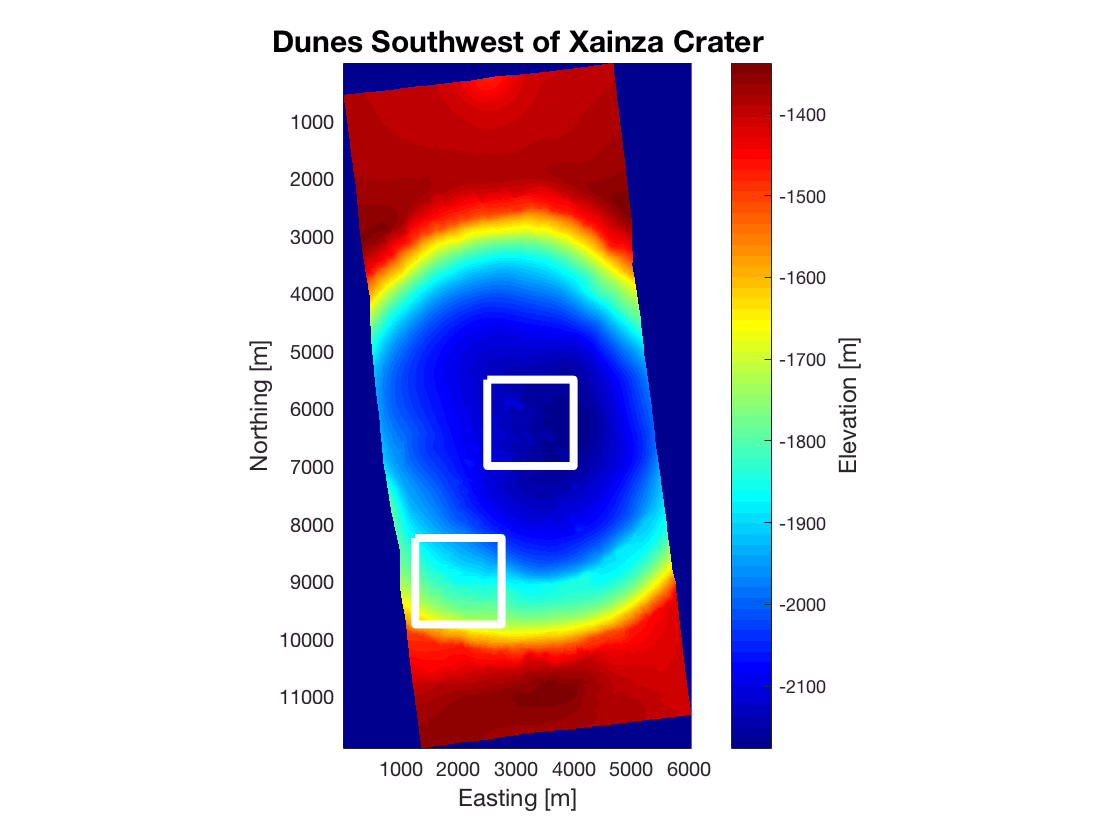

% plots the elevation data
%row (y) and column (x) cropping instructions for the two areas of interest
% region 1
cy1=5500; cy2=7000;
cx1=2500; cx2=4000;
% region 2
cy3=8250; cy4=9750;
cx3=1250; cx4=2750;
figure (1)
clf
hold on
imagesc(dtm2s,clims2)
colormap jet
axis image
c=colorbar;
set(gca,'ydir','rev');
xlabel('Easting [m]','FontSize',12);
ylabel('Northing [m]','FontSize',12);
ylabel(c,'Elevation [m]','FontSize',12);
plot([cx1 cx2 cx2 cx1 cx1],[cy1 cy1 cy2 cy2 cy1],'-w','LineWidth',4)
plot([cx3 cx4 cx4 cx3 cx3],[cy3 cy3 cy4 cy4 cy3],'-w','LineWidth',4)
title('Dunes Southwest of Xainza Crater','FontSize',15);
hold off

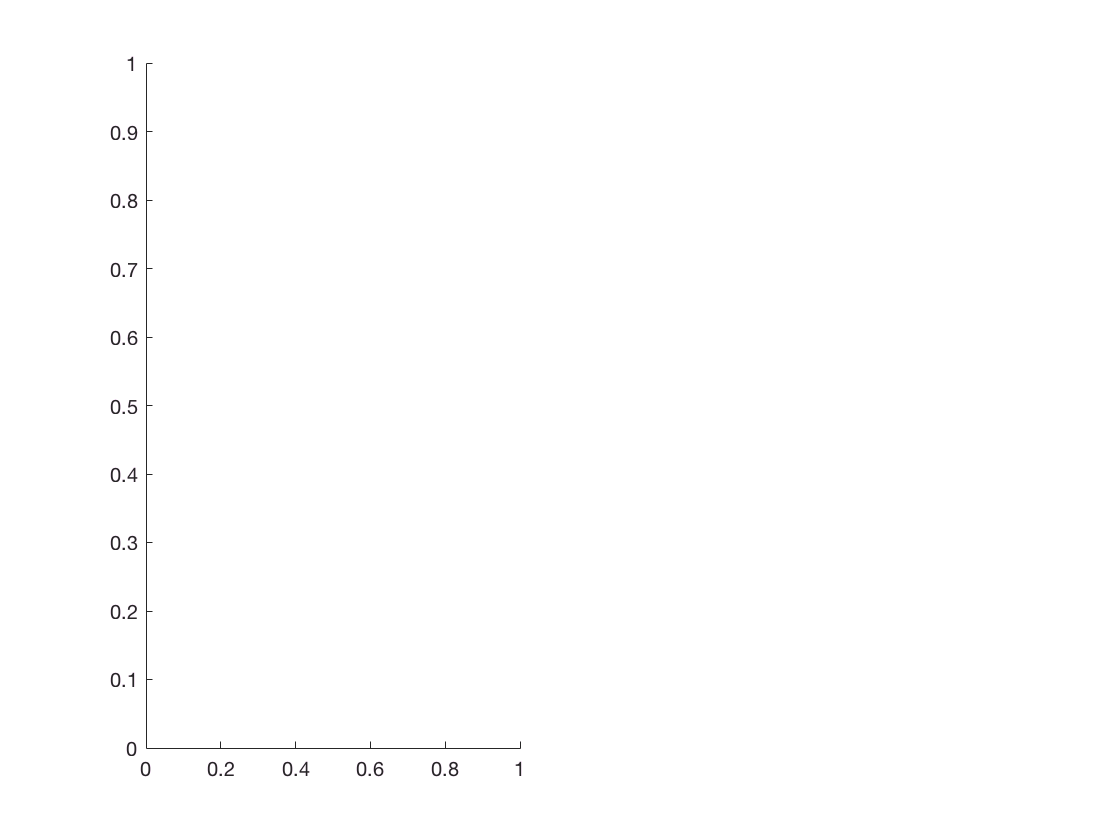

% first image: low elevation
c1dtm = dtm2s(cy1:cy2,cx1:cx2); % crops the first image

lowl1 = [175.8 900.0; 281.0 1040.2]; %define the line you want to draw your transect
[lowcx1,lowcy1,lowcz1] = improfile(c1dtm,lowl1(:,1),lowl1(:,2)); %collect elevations on that line
lowa1 = 90 - ( atan2( (lowl1(2,2)-lowl1(1,2)) , (lowl1(2,1)-lowl1(1,1))) )*180/pi; %compute the cardinal direction of the transect

lowl2 = [9.265 632.673; 110.062 764.1474]; %define the line you want to draw your transect
[lowcx2,lowcy2,lowcz2] = improfile(c1dtm,lowl2(:,1),lowl2(:,2)); %collect elevations on that line
lowa2 = 90 - ( atan2( (lowl2(2,2)-lowl2(1,2)) , (lowl2(2,1)-lowl2(1,1))) )*180/pi; %compute the cardinal direction of the transect

lowl3 = [381.7759 286.4569; 443.1307 483.6686]; %define the line you want to draw your transect
[lowcx3,lowcy3,lowcz3] = improfile(c1dtm,lowl3(:,1),lowl3(:,2)); %collect elevations on that line
lowa3 = 90 - ( atan2( (lowl3(2,2)-lowl3(1,2)) , (lowl3(2,1)-lowl3(1,1))) )*180/pi; %compute the cardinal direction of the transect

lowl4 = [491.3 983.3; 561.5 1101.6]; %define the line you want to draw your transect
[lowcx4,lowcy4,lowcz4] = improfile(c1dtm,lowl4(:,1),lowl4(:,2)); %collect elevations on that line
lowa4 = 90 - ( atan2( (lowl4(2,2)-lowl4(1,2)) , (lowl4(2,1)-lowl4(1,1))) )*180/pi; %compute the cardinal direction of the transect

lowl5 = [732.3745 540.6409; 811.2591 689.6453]; %define the line you want to draw your transect
[lowcx5,lowcy5,lowcz5] = improfile(c1dtm,lowl5(:,1),lowl5(:,2)); %collect elevations on that line
lowa5 = 90 - ( atan2( (lowl5(2,2)-lowl5(1,2)) , (lowl5(2,1)-lowl5(1,1))) )*180/pi; %compute the cardinal direction of the transect

lowl6 = [776.2 939.4; 684.2 1062.2]; %define the line you want to draw your transect
[lowcx6,lowcy6,lowcz6] = improfile(c1dtm,lowl6(:,1),lowl6(:,2)); %collect elevations on that line
lowa6 = 90 - ( atan2( (lowl6(2,2)-lowl6(1,2)) , (lowl6(2,1)-lowl6(1,1))) )*180/pi; %compute the cardinal direction of the transect

lowl7 = [1030.4 926.3; 1043.5 1062.2]; %define the line you want to draw your transect
[lowcx7,lowcy7,lowcz7] = improfile(c1dtm,lowl7(:,1),lowl7(:,2)); %collect elevations on that line
lowa7 = 90 - ( atan2( (lowl7(2,2)-lowl7(1,2)) , (lowl7(2,1)-lowl7(1,1))) )*180/pi; %compute the cardinal direction of the transect

lowl8 = [1354.7 1215.5; 1271.4 1333.9]; %define the line you want to draw your transect
[lowcx8,lowcy8,lowcz8] = improfile(c1dtm,lowl8(:,1),lowl8(:,2)); %collect elevations on that line
lowa8 = 90 - ( atan2( (lowl8(2,2)-lowl8(1,2)) , (lowl8(2,1)-lowl8(1,1))) )*180/pi; %compute the cardinal direction of the transect

subplot(1,2,1)

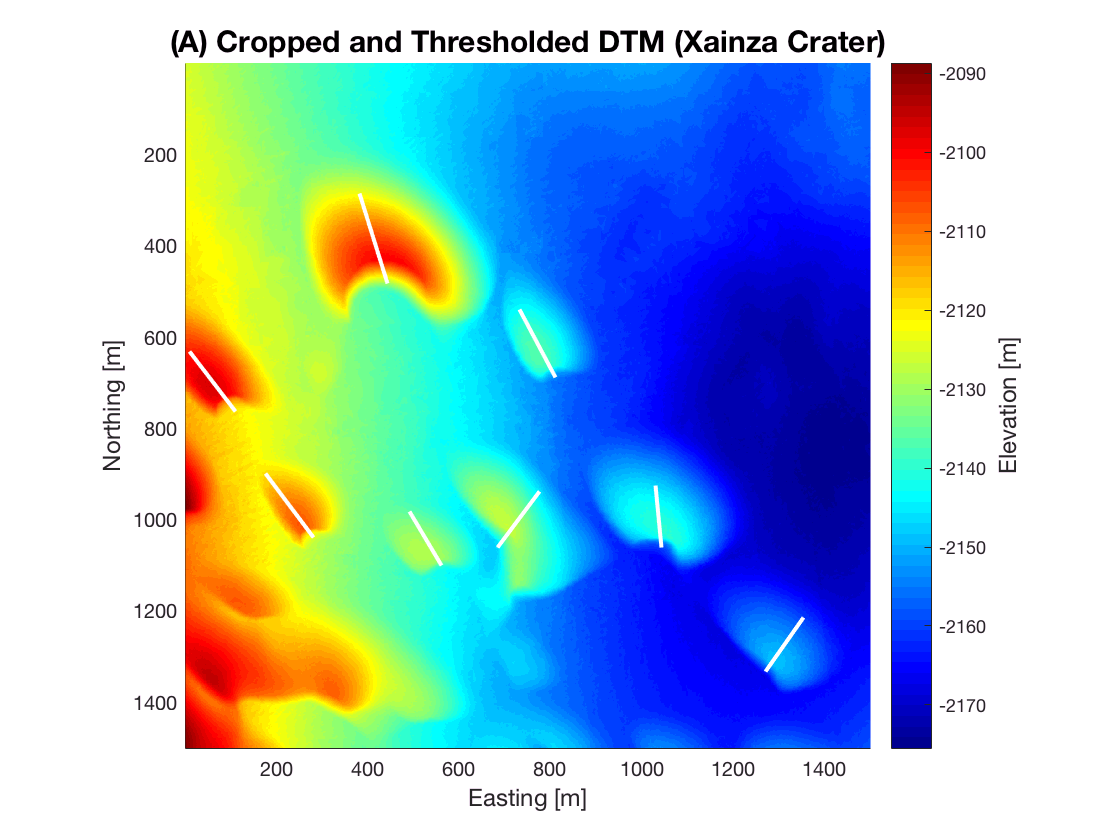

figure (2)
clf
hold on
%imagesc(c1dtm,[min(lowcz8)-6 max(lowcz2)+4]) %threshold image to elevation range of transect ± a few
imagesc(c1dtm)
colormap jet
axis image
c=colorbar;
set(gca,'ydir','rev');
plot(lowl1(:,1),lowl1(:,2),'-w','LineWidth',2)
plot(lowl2(:,1),lowl2(:,2),'-w','LineWidth',2)
plot(lowl3(:,1),lowl3(:,2),'-w','LineWidth',2)
plot(lowl4(:,1),lowl4(:,2),'-w','LineWidth',2)
plot(lowl5(:,1),lowl5(:,2),'-w','LineWidth',2)
plot(lowl6(:,1),lowl6(:,2),'-w','LineWidth',2)
plot(lowl7(:,1),lowl7(:,2),'-w','LineWidth',2)
plot(lowl8(:,1),lowl8(:,2),'-w','LineWidth',2)
xlabel('Easting [m]','FontSize',12)
ylabel('Northing [m]','FontSize',12)
ylabel(c,'Elevation [m]','FontSize',12)
title('(A) Cropped and Thresholded DTM (Xainza Crater)','FontSize',15)
hold off

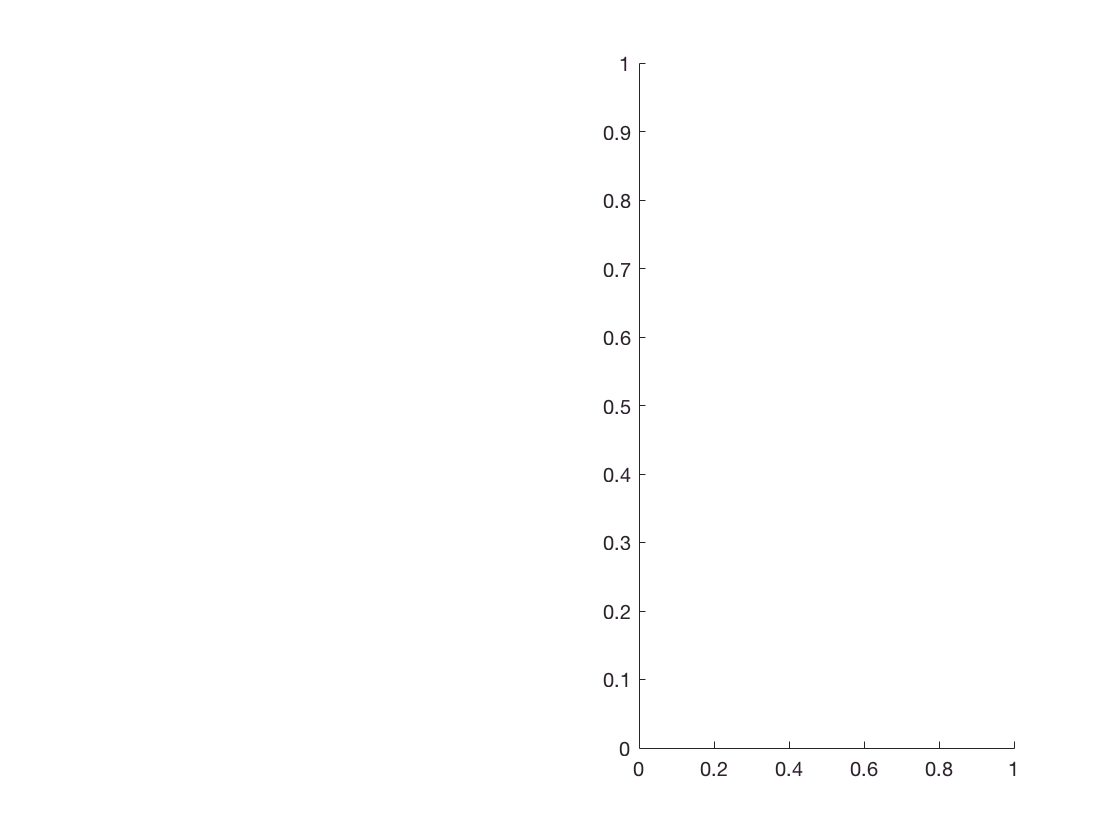

% second image: high elevation
c2dtm = dtm2s(cy3:cy4,cx3:cx4); % crops the first image

highl1 = [429.9832 632.6730; 386.1584 742.2350]; %define the line you want to draw your transect
[highcx1,highcy1,highcz1] = improfile(c2dtm,highl1(:,1),highl1(:,2)); %collect elevations on that line
higha1 = 90 - ( atan2( (highl1(2,2)-highl1(1,2)) , (highl1(2,1)-highl1(1,1))) )*180/pi; %compute the cardinal direction of the transect

highl2 = [578.9876 790.4423; 539.5453 886.8569]; %define the line you want to draw your transect
[highcx2,highcy2,highcz2] = improfile(c2dtm,highl2(:,1),highl2(:,2)); %collect elevations on that line
higha2 = 90 - ( atan2( (highl2(2,2)-highl2(1,2)) , (highl2(2,1)-highl2(1,1))) )*180/pi; %compute the cardinal direction of the transect

highl3 = [403.6883 878.0920; 381.7759 961.3591]; %define the line you want to draw your transect
[highcx3,highcy3,highcz3] = improfile(c2dtm,highl3(:,1),highl3(:,2)); %collect elevations on that line
higha3 = 90 - ( atan2( (highl3(2,2)-highl3(1,2)) , (highl3(2,1)-highl3(1,1))) )*180/pi; %compute the cardinal direction of the transect

highl4 = [351.1 1044.6; 307.3 1132.3]; %define the line you want to draw your transect
[highcx4,highcy4,highcz4] = improfile(c2dtm,highl4(:,1),highl4(:,2)); %collect elevations on that line
higha4 = 90 - ( atan2( (highl4(2,2)-highl4(1,2)) , (highl4(2,1)-highl4(1,1))) )*180/pi; %compute the cardinal direction of the transect

highl5 = [684.2 935.1; 649.1 1031.5]; %define the line you want to draw your transect
[highcx5,highcy5,highcz5] = improfile(c2dtm,highl5(:,1),highl5(:,2)); %collect elevations on that line
higha5 = 90 - ( atan2( (highl5(2,2)-highl5(1,2)) , (highl5(2,1)-highl5(1,1))) )*180/pi; %compute the cardinal direction of the transect

highl6 = [947.1 1097.2; 907.7 1180.5]; %define the line you want to draw your transect
[highcx6,highcy6,highcz6] = improfile(c2dtm,highl6(:,1),highl6(:,2)); %collect elevations on that line
higha6 = 90 - ( atan2( (highl6(2,2)-highl6(1,2)) , (highl6(2,1)-highl6(1,1))) )*180/pi; %compute the cardinal direction of the transect

highl7 = [1183.8 1127.9; 1275.8 1202.4]; %define the line you want to draw your transect
[highcx7,highcy7,highcz7] = improfile(c2dtm,highl7(:,1),highl7(:,2)); %collect elevations on that line
higha7 = 90 - ( atan2( (highl7(2,2)-highl7(1,2)) , (highl7(2,1)-highl7(1,1))) )*180/pi; %compute the cardinal direction of the transect

highl8 = [938.4 987.7; 986.6 1066.5]; %define the line you want to draw your transect
[highcx8,highcy8,highcz8] = improfile(c2dtm,highl8(:,1),highl8(:,2)); %collect elevations on that line
higha8 = 90 - ( atan2( (highl8(2,2)-highl8(1,2)) , (highl8(2,1)-highl8(1,1))) )*180/pi; %compute the cardinal direction of the transect

subplot(1,2,2)

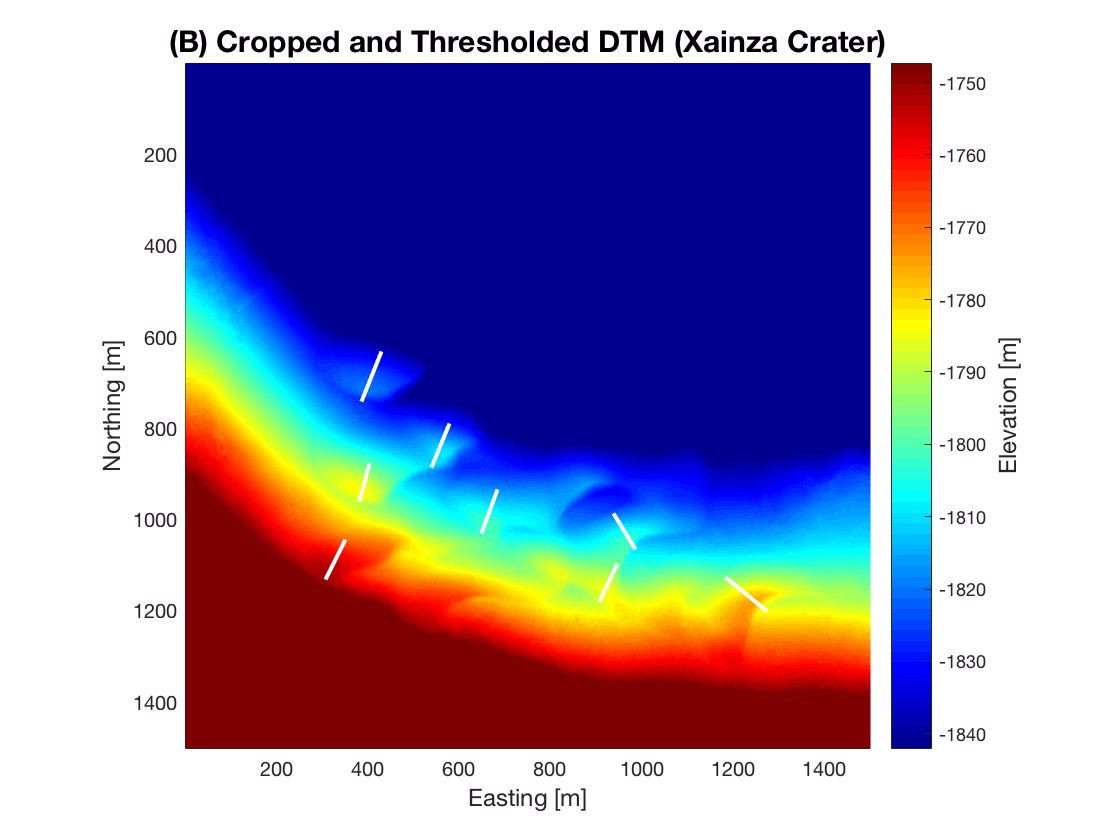

figure (3)
clf
hold on
imagesc(c2dtm,[min(highcz1)-6 max(highcz4)+4]) %threshold image to elevation range of transect ± a few
%imagesc(c2dtm)
%imagesc(c2dtm,[-1870 -1750])
colormap jet
axis image
c=colorbar;
set(gca,'ydir','rev');
plot(highl1(:,1),highl1(:,2),'-w','LineWidth',2)
plot(highl2(:,1),highl2(:,2),'-w','LineWidth',2)
plot(highl3(:,1),highl3(:,2),'-w','LineWidth',2)
plot(highl4(:,1),highl4(:,2),'-w','LineWidth',2)
plot(highl5(:,1),highl5(:,2),'-w','LineWidth',2)
plot(highl6(:,1),highl6(:,2),'-w','LineWidth',2)
plot(highl7(:,1),highl7(:,2),'-w','LineWidth',2)
plot(highl8(:,1),highl8(:,2),'-w','LineWidth',2)
xlabel('Easting [m]','FontSize',12)
ylabel('Northing [m]','FontSize',12)
ylabel(c,'Elevation [m]','FontSize',12)
title('(B) Cropped and Thresholded DTM (Xainza Crater)','FontSize',15)
hold off

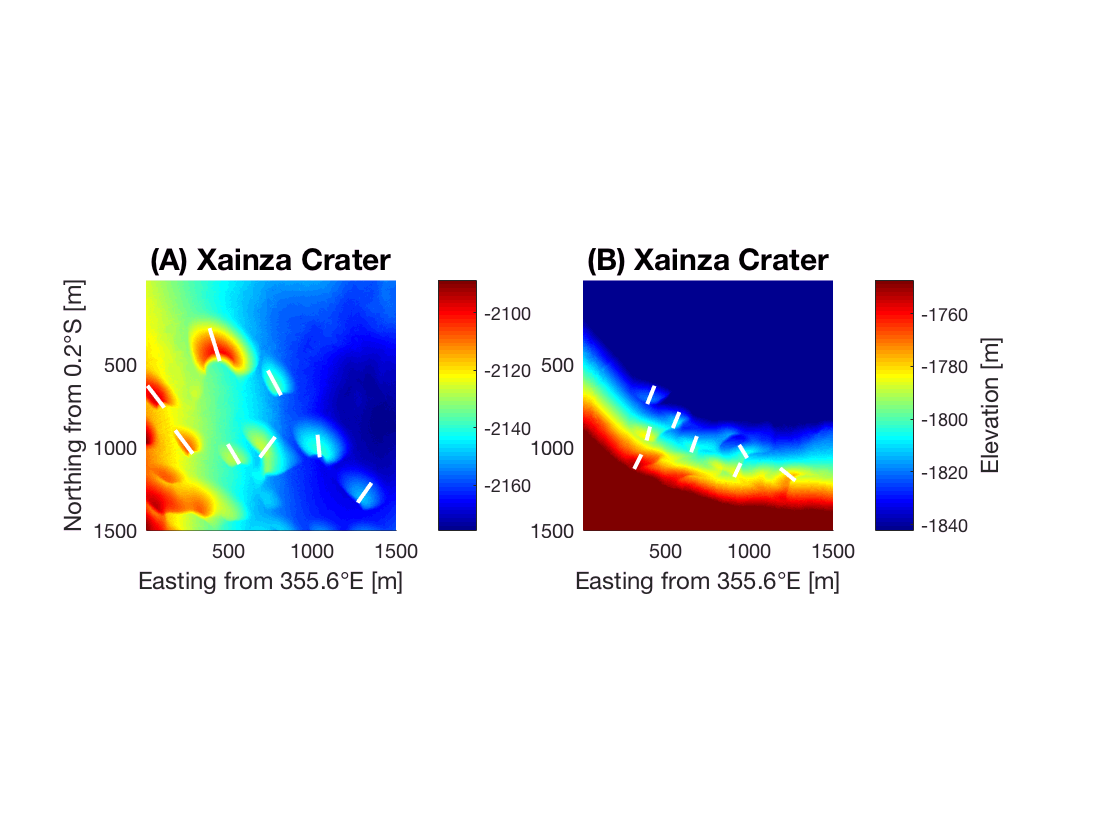

figure (6)
clf
subplot(1,2,1)
hold on
%imagesc(c1dtm,[min(lowcz8)-6 max(lowcz2)+4]) %threshold image to elevation range of transect ± a few
imagesc(c1dtm)
colormap jet
axis image
c=colorbar;
set(gca,'ydir','rev');
plot(lowl1(:,1),lowl1(:,2),'-w','LineWidth',2)
plot(lowl2(:,1),lowl2(:,2),'-w','LineWidth',2)
plot(lowl3(:,1),lowl3(:,2),'-w','LineWidth',2)
plot(lowl4(:,1),lowl4(:,2),'-w','LineWidth',2)
plot(lowl5(:,1),lowl5(:,2),'-w','LineWidth',2)
plot(lowl6(:,1),lowl6(:,2),'-w','LineWidth',2)
plot(lowl7(:,1),lowl7(:,2),'-w','LineWidth',2)
plot(lowl8(:,1),lowl8(:,2),'-w','LineWidth',2)
xlabel(sprintf('Easting from 355.6%cE [m]',char(176)),'FontSize',12)
ylabel(sprintf('Northing from 0.2%cS [m]',char(176)),'FontSize',12)
title('(A) Xainza Crater','FontSize',15)
hold off

subplot(1,2,2)
h = subplot(1,2,2);
p = get(h, 'pos');
p(1) = p(1) - 0.05;
 set(h, 'pos', p);
hold on
imagesc(c2dtm,[min(highcz1)-6 max(highcz4)+4]) %threshold image to elevation range of transect ± a few
%imagesc(c2dtm)
%imagesc(c2dtm,[-1870 -1750])
colormap jet
axis image
c=colorbar;
set(gca,'ydir','rev');
plot(highl1(:,1),highl1(:,2),'-w','LineWidth',2)
plot(highl2(:,1),highl2(:,2),'-w','LineWidth',2)
plot(highl3(:,1),highl3(:,2),'-w','LineWidth',2)
plot(highl4(:,1),highl4(:,2),'-w','LineWidth',2)
plot(highl5(:,1),highl5(:,2),'-w','LineWidth',2)
plot(highl6(:,1),highl6(:,2),'-w','LineWidth',2)
plot(highl7(:,1),highl7(:,2),'-w','LineWidth',2)
plot(highl8(:,1),highl8(:,2),'-w','LineWidth',2)
xlabel(sprintf('Easting from 355.6%cE [m]',char(176)),'FontSize',12)
ylabel(c,'Elevation [m]','FontSize',12)
title('(B) Xainza Crater','FontSize',15)
hold off
figdir='/Users/zhaozhang/frs124/W01';
% Issue the print command, which does the same as "save" it
print('-dpdf',fullfile(figdir,'data1-fig.pdf'))

## Data Analysis and Histograms

lowy1 = lowcz1 + abs(min(lowcz1)); %so we don't have to deal with negative elevations
lowx1 = (1:1:length(lowy1)) .* ( sqrt( (lowcx1(end)-lowcx1(1))^2 + (lowcy1(end)-lowcy1(1))^2) / length(lowcx1)); %distance along the transect
lowx1 = lowx1';

lowy2 = lowcz2 + abs(min(lowcz2)); %so we don't have to deal with negative elevations
lowx2 = (1:1:length(lowy2)) .* ( sqrt( (lowcx2(end)-lowcx2(1))^2 + (lowcy2(end)-lowcy2(1))^2) / length(lowcx2)); %distance along the transect
lowx2 = lowx2';

lowy3 = lowcz3 + abs(min(lowcz3)); %so we don't have to deal with negative elevations
lowx3 = (1:1:length(lowy3)) .* ( sqrt( (lowcx3(end)-lowcx3(1))^2 + (lowcy3(end)-lowcy3(1))^2) / length(lowcx3)); %distance along the transect
lowx3 = lowx3';

lowy4 = lowcz4 + abs(min(lowcz4)); %so we don't have to deal with negative elevations
lowx4 = (1:1:length(lowy4)) .* ( sqrt( (lowcx4(end)-lowcx4(1))^2 + (lowcy4(end)-lowcy4(1))^2) / length(lowcx4)); %distance along the transect
lowx4 = lowx4';

lowy5 = lowcz5 + abs(min(lowcz5)); %so we don't have to deal with negative elevations
lowx5 = (1:1:length(lowy5)) .* ( sqrt( (lowcx5(end)-lowcx5(1))^2 + (lowcy5(end)-lowcy5(1))^2) / length(lowcx5)); %distance along the transect
lowx5 = lowx5';

lowy6 = lowcz6 + abs(min(lowcz6)); %so we don't have to deal with negative elevations
lowx6 = (1:1:length(lowy6)) .* ( sqrt( (lowcx6(end)-lowcx6(1))^2 + (lowcy6(end)-lowcy6(1))^2) / length(lowcx6)); %distance along the transect
lowx6 = lowx6';

lowy7 = lowcz7 + abs(min(lowcz7)); %so we don't have to deal with negative elevations
lowx7 = (1:1:length(lowy7)) .* ( sqrt( (lowcx7(end)-lowcx7(1))^2 + (lowcy7(end)-lowcy7(1))^2) / length(lowcx7)); %distance along the transect
lowx7 = lowx7';

lowy8= lowcz8 + abs(min(lowcz8)); %so we don't have to deal with negative elevations
lowx8 = (1:1:length(lowy8)) .* ( sqrt( (lowcx8(end)-lowcx8(1))^2 + (lowcy8(end)-lowcy8(1))^2) / length(lowcx8)); %distance along the transect
lowx8 = lowx8';

## Section 5: High Elevation Transects and Finding the Peaks (i.e. Amplitudes) of the Dunes

highy1 = highcz1 + abs(min(highcz1)); %so we don't have to deal with negative elevations
highx1 = (1:1:length(highy1)) .* ( sqrt( (highcx1(end)-highcx1(1))^2 + (highcy1(end)-highcy1(1))^2) / length(highcx1)); %distance along the transect
highx1 = highx1';

highy2 = highcz2 + abs(min(highcz2)); %so we don't have to deal with negative elevations
highx2 = (1:1:length(highy2)) .* ( sqrt( (highcx2(end)-highcx2(1))^2 + (highcy2(end)-highcy2(1))^2) / length(highcx2)); %distance along the transect
highx2 = highx2';

highy3 = highcz3 + abs(min(highcz3)); %so we don't have to deal with negative elevations
highx3 = (1:1:length(highy3)) .* ( sqrt( (highcx3(end)-highcx3(1))^2 + (highcy3(end)-highcy3(1))^2) / length(highcx3)); %distance along the transect
highx3 = highx3';

highy4 = highcz4 + abs(min(highcz4)); %so we don't have to deal with negative elevations
highx4 = (1:1:length(highy4)) .* ( sqrt( (highcx4(end)-highcx4(1))^2 + (highcy4(end)-highcy4(1))^2) / length(highcx4)); %distance along the transect
highx4 = highx4';

highy5 = highcz5 + abs(min(highcz5)); %so we don't have to deal with negative elevations
highx5 = (1:1:length(highy5)) .* ( sqrt( (highcx5(end)-highcx5(1))^2 + (highcy5(end)-highcy5(1))^2) / length(highcx5)); %distance along the transect
highx5 = highx5';

highy6 = highcz6 + abs(min(highcz6)); %so we don't have to deal with negative elevations
highx6 = (1:1:length(highy6)) .* ( sqrt( (highcx6(end)-highcx6(1))^2 + (highcy6(end)-highcy6(1))^2) / length(highcx6)); %distance along the transect
highx6 = highx6';

highy7 = highcz7 + abs(min(highcz7)); %so we don't have to deal with negative elevations
highx7 = (1:1:length(highy7)) .* ( sqrt( (highcx7(end)-highcx7(1))^2 + (highcy7(end)-highcy7(1))^2) / length(highcx7)); %distance along the transect
highx7 = highx7';

highy8= highcz8 + abs(min(highcz8)); %so we don't have to deal with negative elevations
highx8 = (1:1:length(highy8)) .* ( sqrt( (highcx8(end)-highcx8(1))^2 + (highcy8(end)-highcy8(1))^2) / length(highcx8)); %distance along the transect
highx8 = highx8';

## Section 6: Evaluate Things for Low and High Elevations

lowamp=[max(lowy1) max(lowy2) max(lowy3) max(lowy4) max(lowy5) max(lowy6) max(lowy7) max(lowy8)];
highamp=[max(highy1) max(highy2) max(highy3) max(highy4) max(highy5) max(highy6) max(highy7) max(highy8)];
lowcard=[lowa1 lowa2 lowa3 lowa4 lowa5 lowa6 lowa7 lowa8];
highcard=[higha1 higha2 higha3 higha4 higha5 higha6 higha7 higha8];

## Section 7: Histograms

%Low and High Elevation Amplitudes
meanlowamp=mean(lowamp);
stdlowamp=std(lowamp);
meanhighamp=mean(highamp);
stdhighamp=std(highamp);

%Histograms of Dune Amplitude
binstep=4; %size of bin
bins = 12:binstep:32; %wavelength bins
hlowamp = hist(lowamp,bins); 
hlowamp = hlowamp./(sum(hlowamp)*binstep); %histogram of manual wavelengths, as a fraction of all samples, normalized to bin area
hhighamp = hist(highamp,bins); 
hhighamp = hhighamp./(sum(hhighamp)*binstep); %histogram of auto wavelengths, as a fraction of all samples, normalized to bin area

% Time for direction
%Low and High Elevation Direction
meanlowcard=mean(lowcard);
stdlowcard=std(lowcard);
meanhighcard=mean(highcard);
stdhighcard=std(highcard);

%Histograms of Dune Direction
binstep2=16; %size of bin
bins2 = -40:binstep2:40; %wavelength bins
hlowcard = hist(lowcard,bins2); 
hlowcard = hlowcard./(sum(hlowcard)*binstep2); %histogram of manual wavelengths, as a fraction of all samples, normalized to bin area
hhighcard = hist(highcard,bins2); 
hhighcard = hhighcard./(sum(hhighcard)*binstep2); %histogram of auto wavelengths, as a fraction of all samples, normalized to bin area

%compute areas under normal curve where we have data
lowamparea=normcdf(max(lowamp),meanlowamp,stdlowamp);
highamparea=normcdf(max(highamp),meanhighamp,stdhighamp);
lowcardarea=normcdf(max(lowcard),meanlowcard,stdlowcard);
highcardarea=normcdf(max(highcard),meanhighcard,stdhighcard);

%fit gaussian distributions to the data to see if the data are normally distributed
gaussamp = (10:0.5:32); %define shorter intervals than the bins defined above, to make smoother curves for plotting
gausscard = (-40:0.5:40);
lowampgauss=normpdf(gaussamp,meanlowamp,stdlowamp);
highampgauss=normpdf(gaussamp,meanhighamp,stdhighamp);
lowcardgauss=normpdf(gausscard,meanlowcard,stdlowcard);
highcardgauss=normpdf(gausscard,meanhighcard,stdhighcard);

% calculates mean squared residual fit
Rlowamp = sqrt(mean((hlowamp.*binstep - (normcdf(bins(1:end)+binstep/2,meanlowamp,stdlowamp) - normcdf(bins(1:end)-binstep/2,meanlowamp,stdlowamp))).^2))*100;
Rhighamp = sqrt(mean((hhighamp.*binstep - (normcdf(bins(1:end)+binstep/2,meanhighamp,stdhighamp) - normcdf(bins(1:end)-binstep/2,meanhighamp,stdhighamp))).^2))*100;
Rlowcard = sqrt(mean((hlowcard.*binstep2 - (normcdf(bins2(1:end)+binstep2/2,meanlowcard,stdlowcard) - normcdf(bins2(1:end)-binstep2/2,meanlowcard,stdlowcard))).^2))*100;
Rhighcard = sqrt(mean((hhighcard.*binstep2 - (normcdf(bins2(1:end)+binstep2/2,meanhighcard,stdhighcard) - normcdf(bins2(1:end)-binstep2/2,meanhighcard,stdhighcard))).^2))*100;

## Section 8: Plots!

figure (5)
clf
subplot(1,2,1)
hold on
b1 = bar(bins,hlowamp);
b1.FaceColor = [0.7 0 0];
b1.BarWidth = 1;
b2 = bar(bins,hhighamp);
b2.FaceColor = [0 0.7 0];
b2.BarWidth = 0.75;
p1 = plot(gaussamp,lowampgauss./lowamparea,'-r','LineWidth',2);
p2 = plot(gaussamp,highampgauss./highamparea,'-g','LineWidth',2);
legend([b1,p1,b2,p2],sprintf('%s=%3.1f%s%3.1f m','\mu',meanlowamp,'\pm',stdlowamp),...
    sprintf('RMSE=%3.1f%%',Rlowamp), ...
    sprintf('%s=%3.1f%s%3.1f m','\mu',meanhighamp,'\pm',stdhighamp), ...
    sprintf('RMSE=%3.1f%%',Rhighamp))
xlabel('Amplitude [m]')
ylabel('Fraction normalized to bin area')
title('Figure 5: Histograms')
grid on
hold off

subplot(1,2,2)
hold on
b3 = bar(bins2,hlowcard);
b3.FaceColor = [0.7 0 0];
b3.BarWidth = 1;
b4 = bar(bins2,hhighcard);
b4.FaceColor = [0 0.7 0];
b4.BarWidth = 0.75;
p3 = plot(gausscard,lowcardgauss./lowcardarea,'-r','LineWidth',2);
p4 = plot(gausscard,highcardgauss./highcardarea,'-g','LineWidth',2);
legend([b3,p3,b4,p4],sprintf('%s=%3.1f%s%3.1f m','\mu',meanlowcard,'\pm',stdlowcard),...
    sprintf('RMSE=%3.1f%%',Rlowcard), ...
    sprintf('%s=%3.1f%s%3.1f m','\mu',meanhighcard,'\pm',stdhighcard), ...
    sprintf('RMSE=%3.1f%%',Rhighcard))
xlabel('Cardinal Direction [m]')
ylabel('Fraction normalized to bin area')
title('Figure 5: Histograms')
grid on
hold off

## Section 9: Professional Plots for LaTeX

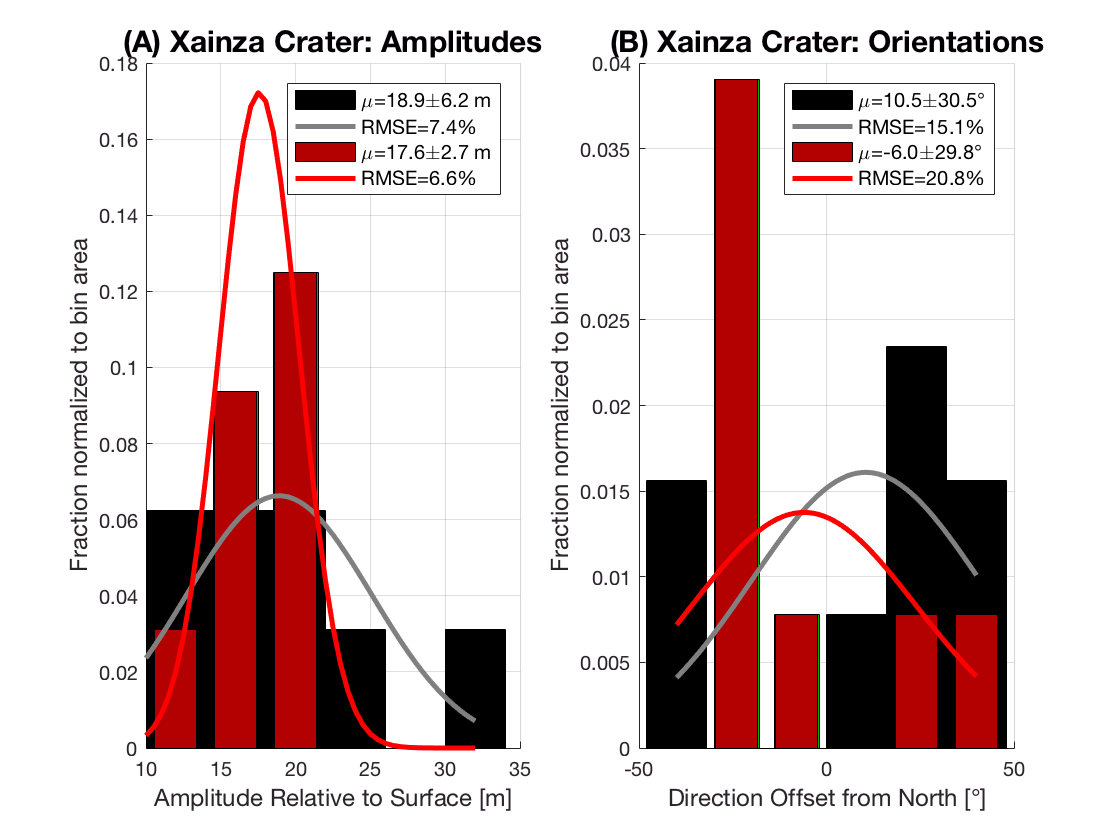

subplot(1,2,1)
hold on
b1 = bar(bins,hlowamp);
b1.FaceColor = [0 0 0];
b1.BarWidth = 1;
b2 = bar(bins,hhighamp);
b2.FaceColor = [0.7 0 0];
b2.BarWidth = 0.7;
p1 = plot(gaussamp,lowampgauss./lowamparea,'-r','LineWidth',2.5);
set(p1, 'color', [0.5 0.5 0.5])
p2 = plot(gaussamp,highampgauss./highamparea,'-r','LineWidth',2.5);
leg1=legend([b1,p1,b2,p2],sprintf('%s=%3.1f%s%3.1f m','\mu',meanlowamp,'\pm',stdlowamp),...
    sprintf('RMSE=%3.1f%%',Rlowamp), ...
    sprintf('%s=%3.1f%s%3.1f m','\mu',meanhighamp,'\pm',stdhighamp), ...
    sprintf('RMSE=%3.1f%%',Rhighamp));
leg1.FontSize=10;
xlabel('Amplitude Relative to Surface [m]','FontSize',12)
ylabel('Fraction normalized to bin area','FontSize',12)
title('(A) Xainza Crater: Amplitudes','FontSize',15)
grid on
hold off

subplot(1,2,2)
% move2 = subplot(2,2,4);
% p=get(move2,'pos');
% p(3) = p(3) + 0.6;
% set(move2, 'pos', p);
hold on
b3 = bar(bins2,hlowcard);
b3.FaceColor = [0 0 0];
b3.BarWidth = 1;
b4 = bar(bins2,hhighcard);
b4.FaceColor = [0.7 0 0];
b4.BarWidth = 0.7;
p3 = plot(gausscard,lowcardgauss./lowcardarea,'-r','LineWidth',2.5);
set(p3, 'color', [0.5 0.5 0.5])
p4 = plot(gausscard,highcardgauss./highcardarea,'-r','LineWidth',2.5);
leg2=legend([b3,p3,b4,p4],sprintf('%s=%3.1f%s%3.1f%c','\mu',meanlowcard,'\pm',stdlowcard,char(176)),...
    sprintf('RMSE=%3.1f%%',Rlowcard), ...
    sprintf('%s=%3.1f%s%3.1f%c','\mu',meanhighcard,'\pm',stdhighcard,char(176)), ...
    sprintf('RMSE=%3.1f%%',Rhighcard));
leg2.FontSize=10;
leg2.Location='northeast';
xlabel(sprintf('Direction Offset from North [%c]',char(176)),'FontSize',12)
ylabel('Fraction normalized to bin area','FontSize',12)
title('(B) Xainza Crater: Orientations','FontSize',15)
grid on
hold off
figdir='/Users/zhaozhang/frs124/W01';
% Issue the print command, which does the same as "save" it
print('-dpdf',fullfile(figdir,'histogram1-fig.pdf'))